% Charger les solutions depuis le fichier
load('solutionsfiltreeCI.mat');

% Affichage des résultats globaux dans un tableau
fprintf('Résultats EN RAD issus de config_robot_redondant_suivitraj_intcimulti et qui sont FILTRES:\n');

Résultats EN RAD issus de config_robot_redondant_suivitraj_intcimulti et qui sont FILTRES:


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp(solutions_filtrees_CI);

    1.0000    1.0000   19.1690  -77.3055   87.7756   -3.0769  -26.3387    9.0000    0.0000
    1.0000    2.0000   18.6179  -70.4709   89.4917   -3.2511  -22.4209    8.9391    1.0448
    1.0000    3.0000   19.9171  -64.8859   89.6042   -2.6069  -19.3780    8.7574    2.0755
    1.0000    4.0000   21.8059  -59.4885   89.1358   -1.9714  -16.6441    8.4572    3.0782
    1.0000    5.0000   23.7281  -53.7157   88.2980   -1.4914  -14.0484    8.0427    4.0392
    1.0000    6.0000   25.9140  -47.9337   87.1024   -1.0891  -11.5743    7.5194    4.9456
    1.0000    7.0000   28.8692  -42.9285   85.7753   -0.7924   -9.3385    6.8944    5.7851
    1.0000    8.0000   32.8148  -39.1401   84.5963   -0.6107   -7.5253    6.1762    6.5464
    1.0000    9.0000   37.3364  -36.0663   83.6138   -0.4645   -6.3119    5.3744    7.2191
    1.0000   10.0000   41.2292  -31.9611   82.3971   -0.0929   -5.8160    4.5000    7.7942
    2.0000    1.0000   36.3243  -65.3505   87.8578  -81.3645    2.8398    9.0000    0.0000

fprintf('------------------------------------------------\n');

------------------------------------------------



% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
solutions_filtrees_CI(:, 3:7) = deg2rad(solutions_filtrees_CI(:, 3:7));
solutions_filtrees_CI(:, 3:7) = mod(solutions_filtrees_CI(:, 3:7), 2*pi);

% Affichage des résultats globaux dans un tableau
fprintf('Résultats EN DEG issus de config_robot_redondant_suivitraj_intcimulti et qui sont FILTRES:\n');

Résultats EN DEG issus de config_robot_redondant_suivitraj_intcimulti et qui sont FILTRES:


fprintf(' CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc\n');

 CI Point  PointTraj    Theta1    Theta2    Theta3    Theta4    Theta5    Xcalc     Ycalc


fprintf('------------------------------------------------\n');

------------------------------------------------


disp(solutions_filtrees_CI);

    1.0000    1.0000    0.3346    4.9339    1.5320    6.2295    5.8235    9.0000    0.0000
    1.0000    2.0000    0.3249    5.0532    1.5619    6.2264    5.8919    8.9391    1.0448
    1.0000    3.0000    0.3476    5.1507    1.5639    6.2377    5.9450    8.7574    2.0755
    1.0000    4.0000    0.3806    5.2449    1.5557    6.2488    5.9927    8.4572    3.0782
    1.0000    5.0000    0.4141    5.3457    1.5411    6.2572    6.0380    8.0427    4.0392
    1.0000    6.0000    0.4523    5.4466    1.5202    6.2642    6.0812    7.5194    4.9456
    1.0000    7.0000    0.5039    5.5339    1.4971    6.2694    6.1202    6.8944    5.7851
    1.0000    8.0000    0.5727    5.6001    1.4765    6.2725    6.1518    6.1762    6.5464
    1.0000    9.0000    0.6516    5.6537    1.4593    6.2751    6.1730    5.3744    7.2191
    1.0000   10.0000    0.7196    5.7254    1.4381    6.2816    6.1817    4.5000    7.7942
    2.0000    1.0000    0.6340    5.1426    1.5334    4.8631    0.0496    9.0000    0.0000

fprintf('------------------------------------------------\n');

------------------------------------------------



% % Convertir les angles de degrés à radians
% solutions_filtrees_CI_radians = deg2rad(solutions_filtrees_CI(:, 3:7));
% 
% % Ramener les angles dans l'intervalle [0, 2*pi]
% solutions_filtrees_CI_radians = mod(solutions_filtrees_CI_radians, 2*pi);

% disp(solutions_filtrees_CI_radians)
% Initialiser une colonne de numéros de configuration initiale
CI_numbers = (1:size(solutions_filtrees_CI_radians, 1)).';


### Visualisation du robot

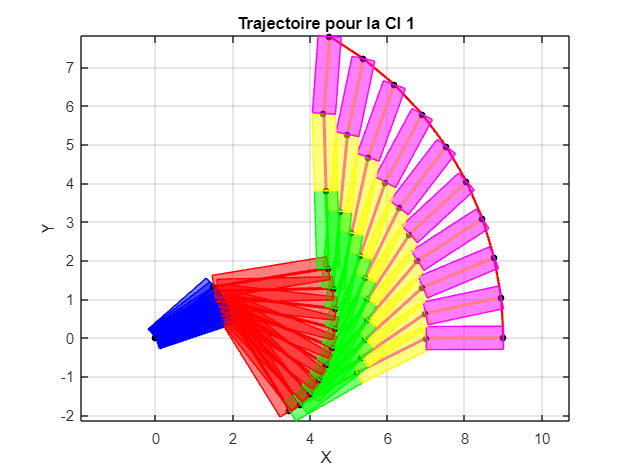

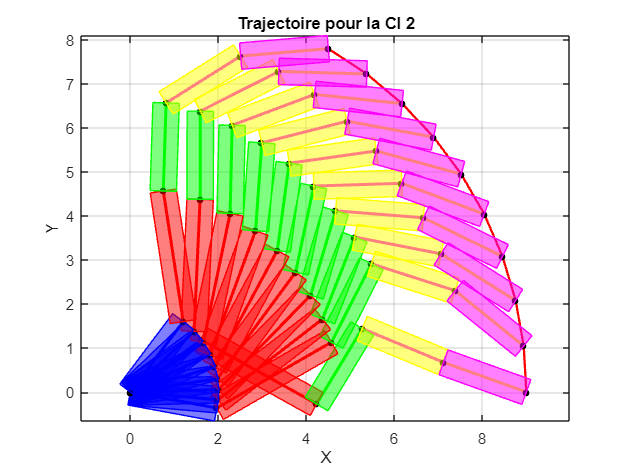

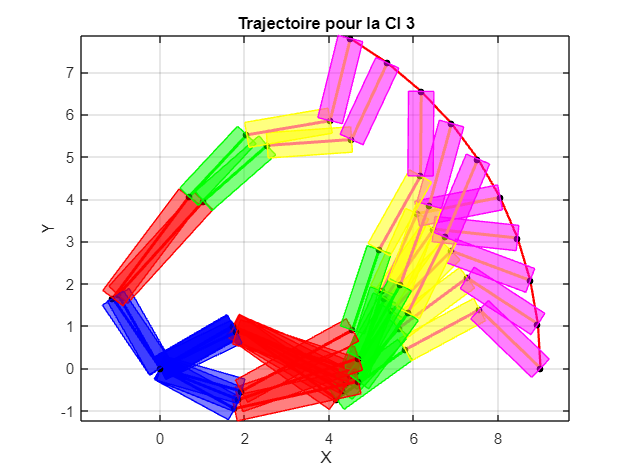

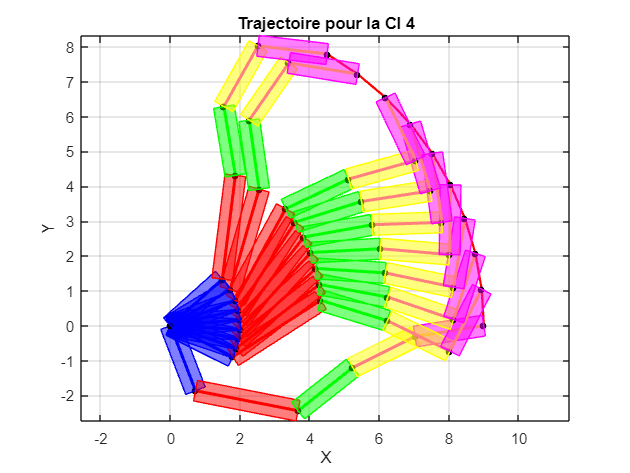

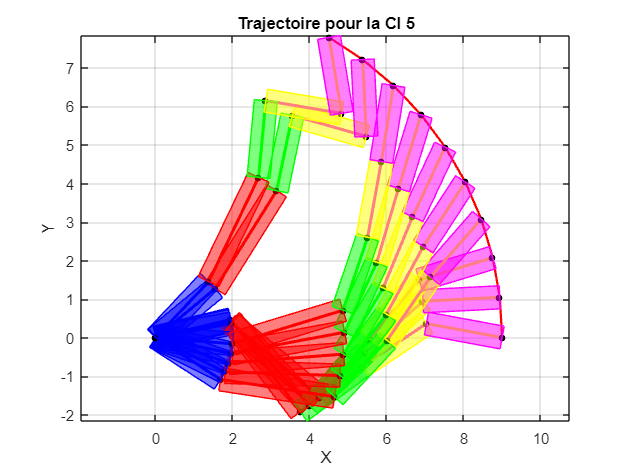

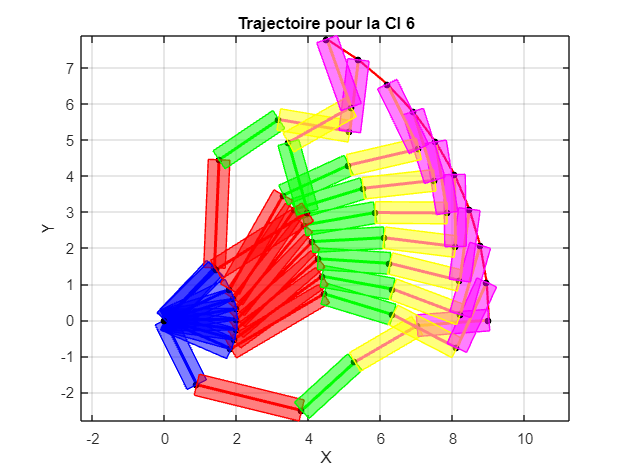

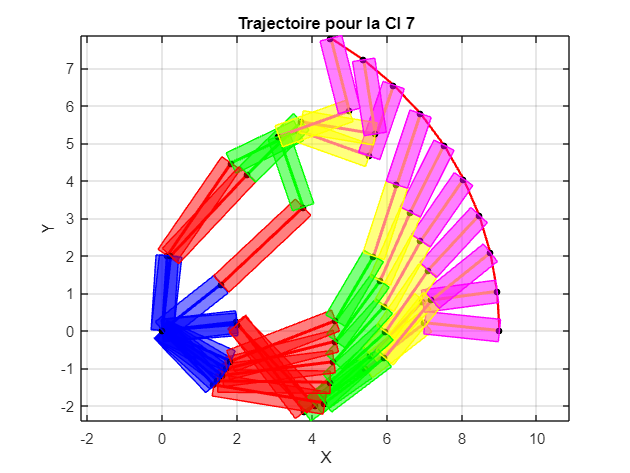

% Pour chaque configuration initiale
for ci = 1:max(solutions_filtrees_CI(:, 1))
    % Extraire les indices correspondant à cette configuration initiale
    indices = solutions_filtrees_CI(:, 1) == ci;
    
    % Extraire les données pour cette configuration initiale
    data_for_ci = solutions_filtrees_CI(indices, :);
    
    % Afficher la trajectoire
    figure;
    plot(x_traj, y_traj, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire à suivre' );
    axis equal; % Pour que l'échelle des axes soit égale
    xlabel('X');
    ylabel('Y');
    title(['Trajectoire pour la CI ', num2str(ci)]);
    grid on;
    hold on;
    
    % Pour chaque point de la trajectoire pour cette configuration initiale
    for i = 1:size(data_for_ci, 1)
        % Extraire les angles d'articulation pour ce point de la trajectoire
        theta1 = data_for_ci(i, 3);
        theta2 = data_for_ci(i, 4);
        theta3 = data_for_ci(i, 5);
        theta4 = data_for_ci(i, 6);
        theta5 = data_for_ci(i, 7);

        % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
        O = [0, 0]; % Position de l'origine
        A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
        B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
        C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
        D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
        E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

        % Tracer le robot pour ce point de la trajectoire
        plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'HandleVisibility', 'off'); % Segment OA
        plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'HandleVisibility', 'off'); % Segment AB
        plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'HandleVisibility', 'off'); % Segment BC
        plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'HandleVisibility', 'off'); % Segment CD
        plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'HandleVisibility', 'off'); % Segment DE
        scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'HandleVisibility', 'off'); % Marques pour les articulations
        % Ajouter des rectangles autour des segments
        rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
        drawSegmentRectangle(O, A, rectWidth, 'b');
        drawSegmentRectangle(A, B, rectWidth, 'r');
        drawSegmentRectangle(B, C, rectWidth, 'g');
        drawSegmentRectangle(C, D, rectWidth, 'y');
        drawSegmentRectangle(D, E, rectWidth, 'm');
        % Mettre en pause pour une durée appropriée
        pause(0.1); % Changer cette valeur pour ajuster la vitesse de l'animation
    end
end

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
end